# Exercício 3

Considere um array de tamanho T que serve de base à implementação de uma memória associativa (por

exemplo em Java). Assuma que a função de hash devolve um valor entre 0 e T −1 com todos os valores

igualmente prováveis.

**alínea a**

Determine por simulação a probabilidade de haver pelo menos uma colisão (pelo menos 2 keys

mapeadas pela função de hash para a mesma posição do array) se forem introduzidas 10 keys num

array de tamanho T = 1000.

N= 1e5;
nposicoes=1000;
nkeys=10;

indices = randi(nposicoes,nkeys,N);

pos_repetidos = true(1,N);

for i=1:N
    pos_repetidos(i) = length(unique(indices(:,i))) == nkeys;
end

prob= 1 - (sum(pos_repetidos)/N)

prob = 0.0452

**alínea b**

Faça um gráfico da probabilidade da alínea (a) (estimada por simulação) em função do número de

keys para todos os valores relevantes num array de tamanho T = 1000.

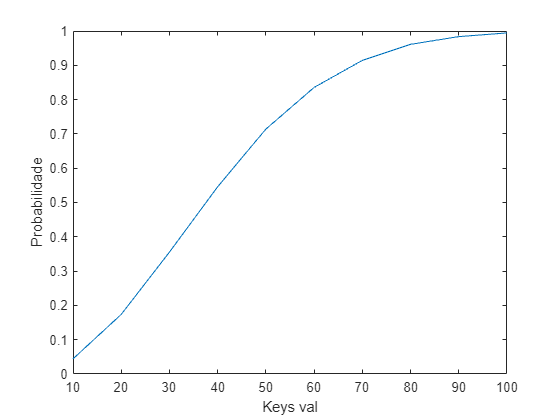

k=10:10:100;
probabilidades=zeros(1,length(k));

for j=1:length(k)
    N= 1e5;
    nposicoes=1000;
    nkeys=k(j);
    
    indices = randi(nposicoes,nkeys,N);
    
    pos_repetidos = true(1,N);
    
    for i=1:N
        pos_repetidos(i) = length(unique(indices(:,i))) == nkeys;
    end
    
    prob= 1 - (sum(pos_repetidos)/N);
    probabilidades(j)=prob;
    
end


plot(k,probabilidades)


**alínea c**

Para um número de keys igual a 50, represente graficamente a variação da probabilidade (estimada

por simulação) de não haver nenhuma colisão em função do tamanho T do array (assuma os

tamanhos T de 100 até 1000 com incrementos de 100).

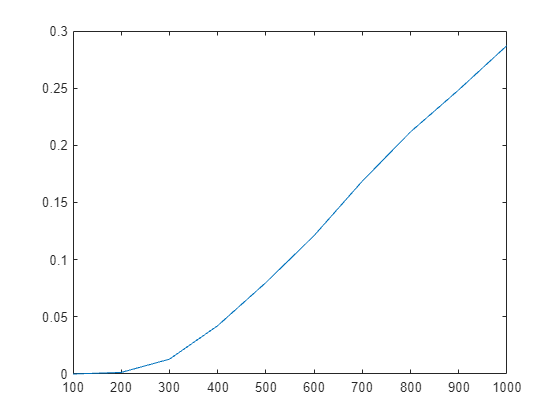

nkeys=50;
T=100:100:1000;

for j=1:length(T)
    N= 1e5;
    nposicoes=T(j);
  
    
    indices = randi(nposicoes,nkeys,N);
    
    pos_repetidos = true(1,N);
    
    for i=1:N
        pos_repetidos(i) = length(unique(indices(:,i))) == nkeys;
    end
    
    prob= (sum(pos_repetidos)/N);
    probabilidades(j)=prob;
    
end

plot(T,probabilidades)


ylabel("Probabilidade");
xlabel("Keys val");


